# Plantilla problema práctica 1 Model. Exp.

Es necesario cargar los datos suministrados por la empresa en este punto

clc; clear;
load('DataP1ModExp/data1.mat')

## Preguntas

- ¿Qué es esfuerzo de muestreo?

- ¿Cómo ver el número de frecuencias distintas de la PRBS?

- ¿Por qué escoge 900 si probó para 1000?

## Resumén

- Estamos antes un modelo SISO no lineal y vamos a identificarlo mediante un sistema lineal.

- En condiciones regulares la entrada tiene un valor de 1000 y se mantiene en estado estacionario de $571.9318$.

- Partiendo del punto de estabilidad, se varió la entrada de 500  a 1500 con tamaño de paso de 10.

- Decidió hacer un experimento variando la entrada de 1000 a 1120 partiendo del mismo punto de estabilidad.

- Escogió un periodo de muestreo de una hora con una PRBS entre 900 y 1120 para identificar el sistema.

$u_{lineal}$: Función afín (500:10:1500).

$y_{sample}$: Respuesta a $u_{lineal}$ desde el punto estacionario de $571.9318$ -`unique(y_sample(:,1))`-.

$y_{response}$: Respuesta de la salida a una función escalon de 1000 a 1120.

$y$: Respuesta a la PRBS, pero restandole el primer valor a la serie.

$u$: PRBS entre -100 y y 120 (900 y 1120).

## Petición de la empresa

Cordial saludo ingenieros matemáticos. Nos comunicamos con ustedes porque necesitamos determinar un modelo para el comportamiento de cierta planta ultra secreta. Como podrán comprender, nos vemos en la obligación de reservarnos la mayor cantidad de información posible. Nosotros mismos ya hemos adelantado parte de los procesos necesarios para determinar el modelo. Sabemos que nuestra planta consta de una única entrada y una única salida, la entrada tiene un valor de 1000 unidades regularmente y la planta se mantiene en estado estacionario. Partiendo de este punto de estabilidad, nuestro anterior ingeniero varió el valor de la entrada en un rango de 500 a 1500 $(u_{lineal})$ tal y como pueden ver a continuación

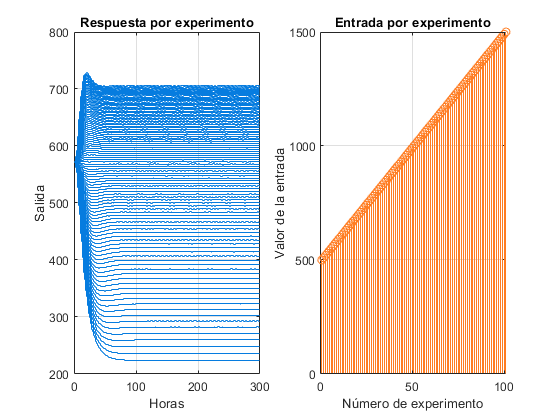

figure('Color', 'White')
subplot(1,2,1)
stairs(0:300,y_sample','Color', my_color('blue1'))
grid on
title('Respuesta por experimento')
xlabel('Horas'); ylabel('Salida')
subplot(1,2,2)
stem(u_lineal, 'Color', my_color('orange'))
grid on
title('Entrada por experimento')
xlabel('Número de experimento'); ylabel('Valor de la entrada')

Esta información se las compartimos a través de la matriz **y_sample** y el vector **u_lineal**. La primera fila de la matriz corresponde con el primer valor del vector como entrada. Para cada caso, se tomaron muestras del estado del sistema cada hora y esperamos hasta que el sistema se estabilizara. Luego, para un solo experimento, se aumentó lo máximo posible el esfuerzo de muestreo y se cambió la entrada del sistema de $1000$ a $1120$ de forma abrupta. Los datos de la respuesta del modelo se presentan a continuación:

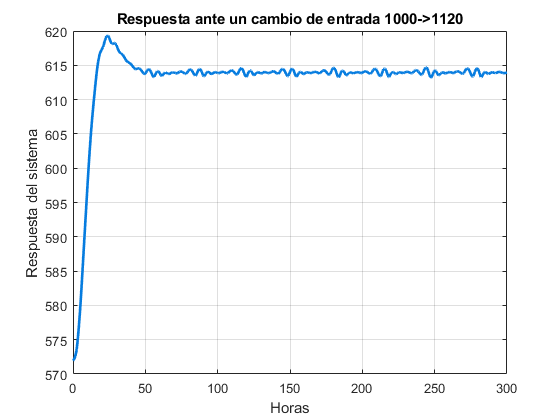

figure(2)
clf
% plot(t, y_sample(find(u_lineal==1120),:))
plot(t,y_response, 'LineWidth', 2, 'Color', my_color('blue1'))
grid on
xlabel('Horas')
ylabel('Respuesta del sistema')
title('Respuesta ante un cambio de entrada 1000->1120')

Con base en dicha información, nuestro anterior ingeniero decidió excitar el sistema con un periodo de muestreo de 1 hora y una señal PRBS (con un periodo igual al de muestreo) que variaba entre valores de 900 y 1120 para luego proceder a identificar un modelo apropiado para la planta, sin embargo, tuvimos que prescindir del ingeniero en este punto y el sistema no ha podido identificarse. Los datos recopilados se muestran a continuación

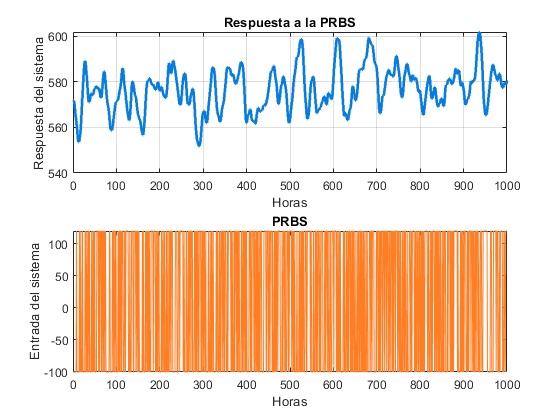

figure(3)
clf
subplot(2,1,1)
stairs(0:1000, y', 'LineWidth', 2, 'Color', my_color('blue1'))
grid on
title('Respuesta a la PRBS')
xlabel('Horas'); ylabel('Respuesta del sistema')
subplot(2,1,2)
plot(0:1000, u, 'Color', my_color('orange'))
xlabel('Horas'); ylabel('Entrada del sistema')
title('PRBS')

Nos hemos contactado con ustedes con la esperanza de que puedan evaluar la metodología que siguió nuestro anterior ingeniero (si es adecuada o si modificarían algo) y, en caso de que lo consideren posible, concluir el proceso de identificación del sistema. Les solicitamos el mayor detalle posible en sus respuestas así como en la justificación de porqué deberíamos confiar o no en el modelo que ustedes puedan identificar. Estaremos muy atentos. 

## Respuesta a la empresa

### Preeliminares

- Curva de linealización

- Respuesta a un escalon, estimación de segundo orden de los parámetros.

- Orden 2m mínimo.

- Teorema de continuidad de los parámetros

### Análisis trabajo previo

**Procedimiento 1: **El ingeniero anterior comenzó observando en que rango de la entrada el sistema se comporta de manera lineal. Para esto varió la entrada de $500$ a $1500%$ con tamaño de paso fijo de $10$. 

**Comentario:** Esto tiene sentido desde la matemática, puesto que escogió un intervalo centrado en la entrada usual y seleccionó un tamaño de paso fijo (una práctica común). No obstante, desconocemos si esta elección es consistente con el funcionamiento interno de la empresa, por lo que conviene contestar las siguientes preguntas: ¿este es un rango factible? ¿Una variación de 10 en la entrada es pequeña, sin serlo en exceso? Si las respuestas son afirmativas, consideramos que fue una elección adecuada.

**Procedimiento 2:** Para un solo experimento, se aumentó lo máximo posible el esfuerzo de muestreo y se cambió la entrada del sistema de $1000$ a $1120$ de forma abrupta.

**Comentario:** La elección de los parámetros de la función escalón empleada para la entrada debe corresponder a la región lineal y de mayor amplitud de la **curva de linealización** respecto a la entrada. Claramente, dicha región debe ser consistente con los valores de entrada que la empresa suele manejar. No tenemos resultados sobre estos procedimientos así que procedemos a realizarlo. Sin embargo, es evidente que la curva de linealización será no lineal concava hacia abajo, puesto que el punto de estabilización aumenta cada vez menos ante cambios constantes en la entrada. Es decir, estamos ante la presencia de un proceso con producción marginal decreciente.

**Resultados: **Comenzamos graficando la curva de linealidad y el intervalo escogido. Claramente, este rango es una buena aproximación lineal, no obstante, es cuestionable su elección, pues se podría obtener un rango más amplio o desplazado. Esto dependerá de las necesidades de la empresa, es decir, la región deseada de variación de la entrada y la precisión deseada.

Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)     225.51         3.176    71.005    5.3714e-16
    x1             0.34727     0.0029944    115.97    2.4507e-18


Number of observations: 13, Error degrees of freedom: 11
Root Mean Squared Error: 0.404
R-squared: 0.999,  Adjusted R-Squared: 0.999
F-statistic vs. constant model: 1.34e+04, p-value = 2.45e-18


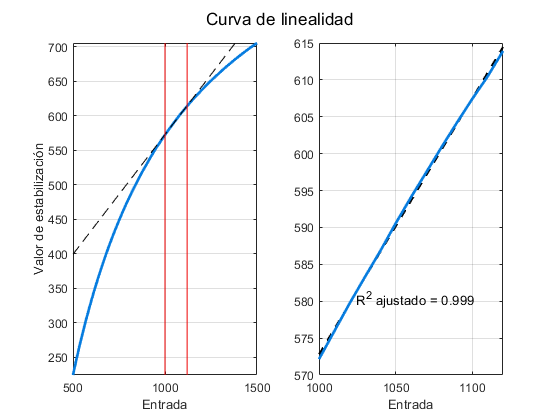

u_min = 1000;
u_max = 1120;

if (u_min < u_max)
    est = y_sample(:, end)'; % Estimación puntos de estabilidad.
    linear_curve(est, u_lineal, u_min, u_max)
else
    disp('Invalid input limits')
end

**Conclusión:** La elección no es erronea pero no necesariamente es óptima, es posible aumentar el rango de la entrada o desplazarlo y obtener significancia en el modelo de regresión lineal y un excelente ajuste. Esto dependerá de las necesidades de la empresa. Considerando que desconocemos dicha información asumimos que la empresa concuerda con los efectos prácticos de la elección del ingeniero.

**Procedimiento 3:** Elección de un periodo de muestreo de excitación de 1 hora.

**Comentario: **Para dicha elección se suele emplear una aproximación de segundo orden para el sistema de $\frac{t_r}{10}$, donde $t_r$ el periodo de crecimiento, es decir, el tiempo que tarda el proceso en pasar del $10\%$ del valor de estabilización al $90\%$. Cabe resaltar, que un valor en el intervalo $\left[\frac{t_r}{15}, \frac{t_r}{5}\right]$es aceptable. No tenemos resultados sobre estos procedimientos así que procedemos a realizarlo.

**Resultados:** Se observa que $(t_r/15, t_r/10, t_r/15) = (0.7066, 1.06, 2.12)$.

[T, M_p, delta_y] = order2_plot(t, y_response - y_response(1));
tr = T(2) ./ (15:-5:5);
disp(['Tiempo de muestreo apropiado:', num2str(tr(2)), ' horas.'])

Tiempo de muestreo apropiado:1.06 horas.


disp(['Intervalo tiempo de muestreo apropiado: [', num2str(tr(1)) ', ', num2str(tr(3)), '] horas.'])

Intervalo tiempo de muestreo apropiado: [0.70667, 2.12] horas.



% Se valida la eleccion del periodo.
% Faltó.

**Conclusión.** La elección del periodo de muestreo es apropiada.

**Procedimiento 4:**  Para excitar el sistema, escogió una señal PRBS (con un periodo igual al de muestreo) que variaba entre valores de 900 y 1120.

**Comentarios: **Sabemos que para identificar un modelo de orden $m$, se requiere que la PRBS sea mínimo de orden $2m$. Por otra parte, es importante analizar si la amplitud de la PRBS saca al sistema de la región de linealidad.

**Resultados: **Dado que desconocemos el orden de la PRBS con la que el ingeniero anterior excitó el sistema, procedemos a estimarla mediante la función `pexcit`, la cual retorna un orden estimado de 50.

pexcit(iddata(y, (u+1000)', 1))

ans = 50

params_prbs(u)

ans = struct with fields:
        n: 1001
    A_max: 120
    A_min: -100
    order: 9
     freq: [1 2 3 4 5 6 7 8 10]


Por otra parte, en el procedimiento 2, se había concluido para en el intervalo $[1000, 1120]$ tenemos una región de linealidad. Sin embargo, en este experimento, el ingeniero decidió extender el intervalo de la entrada para estuviera quasi-centrado en el valor usual. Bajo los supuestos anteriores se observa que en el nuevo intervalo $[900, 1120]$ puede considerarse un rango de linealidad, además el punto de operación sigue perteneciendo al intervalo, por lo que el teorema de dependencia continua de los parámetros indica que ambas regiones son aproximaciones lineales similares.

u_min = 900;
u_max = 1120;

if (u_min < u_max)
    est = y_sample(:, end)'; % Estimación puntos de estabilidad.
    linear_curve(est, u_lineal, u_min, u_max)
else
    disp('Invalid input limits')
end

Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     190.86       4.5994    41.498    1.2234e-21
    x1             0.37984     0.004544    83.591    5.5018e-28


Number of observations: 23, Error degrees of freedom: 21
Root Mean Squared Error: 1.45
R-squared: 0.997,  Adjusted R-Squared: 0.997
F-statistic vs. constant model: 6.99e+03, p-value = 5.5e-28


**Conclusiones:** La PRBS definida por el ingeniero parece tener sentido. Por ejemplo, el orden de la misma es suficiente para disponer de una amplia gama de modelos. No obstante, se resalta que el intervalo de la PRBS al ser más extenso comienza a mostrar una región que para el observador más riguroso no sería una región de linealidad. Así las cosas, resulta conveniente tener comunicación directa con la empresa, para ver si esto les representa un problema o si está en sintonía con las necesidades de la misma. En caso de que no ser así, se debe volver a realizar el experimento con una nueva parametrización.

### Preprocesamiento de datos

#### Eliminación de outliers

Comenzamos realizando una amputación de datos atípicos. Para esto establecemos varios criterios:

- **Tradicional.** Observaciones a más de tres desviaciones estándar de la media.

- **Robusto.** Observaciones que estén a más de tres veces la MAD escalada respecto a la mediana. Donde la MAD escalada se define como `c*median(abs(A-median(A)))`, con `c=-1/(sqrt(2)*erfcinv(3/2))`. 

- **No paramétrico.** Observaciones a más de 1.5 veces el rango intercuantil desde los cuántiles.

- **Datos gausianos 1. **Asumiendo normalidad elimina uno por uno las observaciones con base al la **prueba de Grubb**.

- **Datos gausianos 2. **Elimina las observaciones una por una con base a la prueba generalized extreme Studentized deviate test, funciona mejor que la prueba de Grubb cuando hay valores atípicos enmascarados por otros.

Cabe resaltar, que antes de realizar la amputación, debemos validar si los datos son normales. A partir de un gráfico cuantil-cuantil es evidente que los datos no siguen una distribución normal por el comportamiento extraño de las colas. Por su parte, el histograma valida estas conclusiones, parece que los datos siguen una distribución con crestas. Por lo tanto, no realizamos amputación de datos con pruebas gaussianas.

ans = struct with fields:
    alpha: 0.0500
       ad: {'Anderson-Darling'  'H1'  'H0: Normalidad con enfasis en las colas.'}
       jb: {'Jarque-Bera'  'H0'  'H0: Mean and Variance of normal distriution.'}
     chi2: {'Chi-square goodness-of-fit'  'H1'  'H0: Mean and Variance of normal distriution.'}


checkGaussian1d(y, 0.05)

Procedemos analizar los datos atípicos estimados por cada métodos y encontramos que solo el no parámetrico indica la existencia de dos observaciones atípicas. No obstante, lo es por muy poco y estos pueden darnos información interesante sobre el proceso así que consideramos que no hay datos atípicos y por tanto no realizamos la amputación de estos.

Datos amputados por el método tradicional:


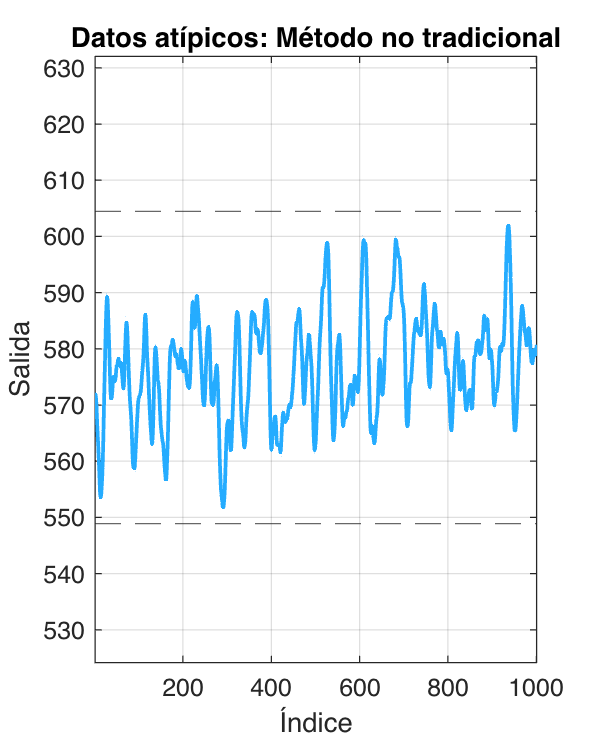


ans =

  1×0 empty double row vector



plot_outliers(y, 'mean')

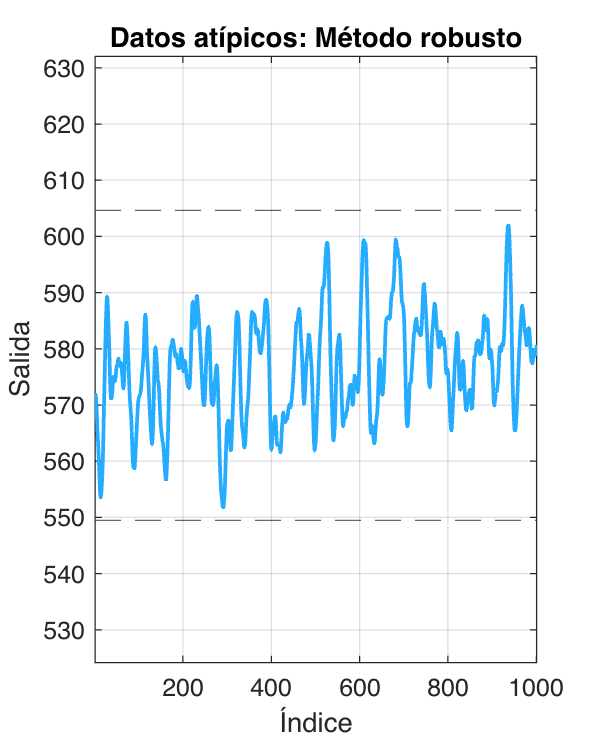


ans =

  1×0 empty double row vector



plot_outliers(y, 'median')

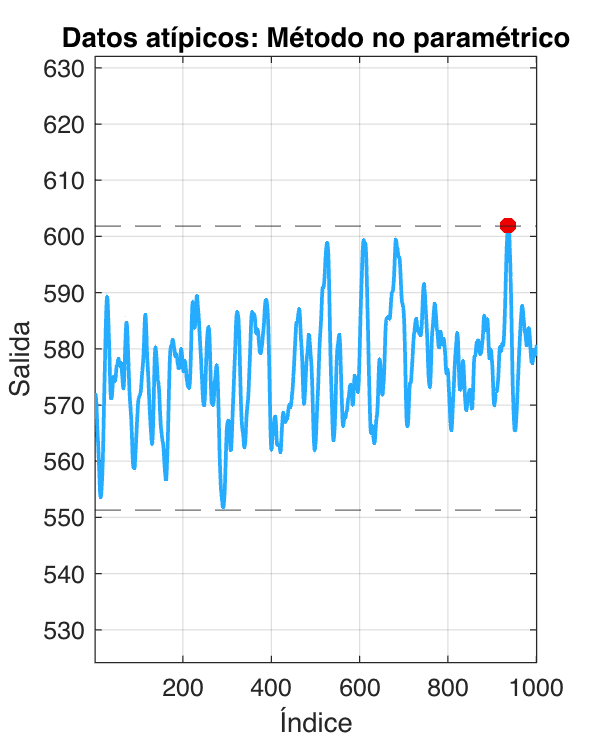

ans =    936   937


plot_outliers(y, 'quartile')

#### Tendencia y media cero


pp = detrend(y);

Arrays have incompatible sizes for this operation.

Related documentation

pp = pp - mean(pp);
plot(pp, 'LineWidth', 1.5, 'Color', my_color('blue'))
hold on; grid on
plot(y - mean(y), 'LineWidth', 1.5, 'Color', my_color('red'))
legend({'Nuevo', 'Baja frecuencia'})

clf
subplot(3,1,1)
autocorr(pp)
subplot(3,1,2)
parcorr(pp)
subplot(3,1,3)
crosscorr(u, pp)



Mdl = arima(0, 0, 4);
Est = estimate(Mdl, pp')

 
    ARIMA(0,0,4) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.077086       0.24464        0.31511         0.75268
    MA{1}         1.8987       0.11961         15.873      9.6972e-57
    MA{2}            1.5       0.13052         11.493      1.4355e-30
    MA{3}              1       0.13153         7.6027      2.9011e-14
    MA{4}        0.47432       0.11983         3.9584      7.5466e-05
    Variance      2.4286       0.19065         12.739      3.5997e-37



Est =   arima with properties:

     Description: "ARIMA(0,0,4) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 0
               D: 0
               Q: 4
        Constant: 0.0770859
              AR: {}
             SAR: {}
              MA: {1.89867 1.5 1 0.47432} at lags [1 2 3 4]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 2.42862

sim = 1.8*simulate(Est, 1001);

figure()
plot(pp, 'Color', my_color('blue'))
hold on; grid on
plot(sim, 'Color', my_color('red'))
hold off
legend({'Salida', 'MA(4)'})

r2 = rsquare(pp, sim);
disp(['R2: ', num2str(r2)])

R2: 0.88949


### Identificación del modelo

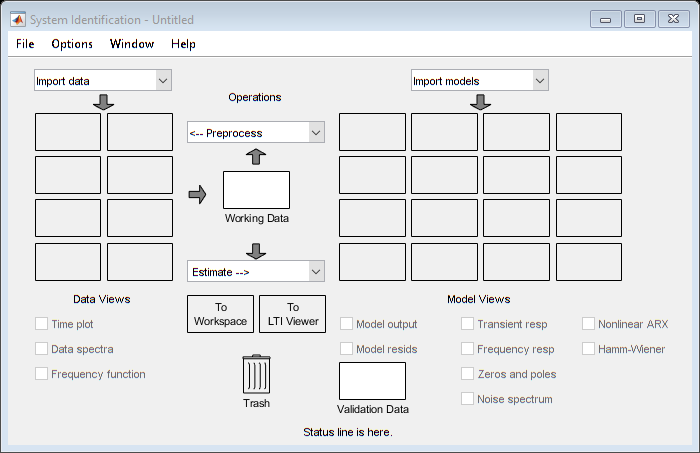

systemIdentification